## TOPIC 26: User interfaces and beyond

ENGR105, 12/3/20

#### Example problem: simulating cancer growth

A new model of cancer growth is proposed by a famous cancer biologist and you are asked to implement it. The main hypothesis of the model is that a cell can **switch** between a **normal (0)** and **cancerous (1)** state based on **probability **and** the** **state of its neighboring cell**. 

That is, a ***normal cell may become ******cancerous*** if it is *adjacent to many**** neighboring ******cancer****** cells***, and a ***cancerous cell may become ******normal*** if it is *adjacent to few or no**** neighboring ******cancer****** cells***. The model treats a population of cells in a tissue as a (2-D) square matrix. Each entry in the matrix corresponds to a cell and can take one of two possible values: an entry of 0 corresponds to a normal cell and an entry of 1 corresponds to a cancerous cell. One such initial state matrix is shown here:

            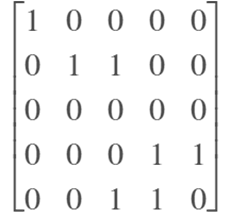

In your simulation, you let the system evolve based on the **following rules**, which are applied in each** simulation time step**. That is, these rules are applied to each matrix element (*i.e.* each cell) of the **current state** to produce **a new matrix** corresponding to the **next state**.

- Any cancerous cell with **2 or fewer cancerous neighbors** has a **25% **chance of becoming normal.

- Any normal cell with **3 or 4 cancerous cell neighbors** has a **50%** chance of becoming cancerous.

- Any normal cell with **5 or more cancerous cell neighbors** becomes cancerous.

- In all other cases, the cell retains its previous state.

Produce a computational solution that uses the rules described above to update the matrix from one **simulation time step **to the next. **Iterates through 100 simulation time steps**, producing a **final state matrix** that is displayable.

**First thing: write pseuodcode**

% Create an initial state matrix -> can use randi()

% For each simulation time step, do the following:

% 1) loop through all indices of the matrix corresponding to the start of
% that time step

% 2) Determine how many neighboring cells are cancerous 

% 3) Apply rules to a "next state" matrix 
% NOTE: we are not overwriting the current state matrix 


% update current state matrix to be the next state

**Step 1: create an initial system matrix**

- Eventually, we will want to analyze all neighboring values around a given index. To potentially make this easier later on, we will create an initial system matrix surrounded by `NaN`s

- This will enable us to easily create `3x3` submatrices for each matrix element. Each of these will contain the neighboring elements.

% Create a matrix to store the initial state of the system. Note: we
% will surround it with NaNs
currentState = nan(7);
currentState(2:6,2:6) = randi(2,[5,5]) - 1;
disp(currentState)

   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN     0     1     1     0     0   NaN
   NaN     0     0     0     1     0   NaN
   NaN     0     0     0     0     0   NaN
   NaN     0     1     1     0     1   NaN
   NaN     0     0     0     1     0   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN



**Step 2: perform one simulation time step**

- After one simulation time step, the above initial state matrix should be updated according to the above rules

% Preallocate matrix to store the system matrix after one time step
nextState = currentState;

% Loop through all row/column indices of the system matrix
for r = 2:6       % Rows
    for c = 2:6     % Columns
        
        % Determine state of the cell of interest
        cellOfInt = currentState(r,c);
        
        % Create a submatrix containing the immediate neighbors
        cellAndSurround = currentState(r-1:r+1,c-1:c+1);
        
        % Set cell of interest to nan
        cellAndSurround(2,2) = nan;
        
        % Remove NaNs
        cellAndSurround = cellAndSurround(~isnan(cellAndSurround));
        
        % Identify number of cancerous neighbors
        numCan = sum(cellAndSurround,'all');
        
        % If cell is normal and >= 5 cancerous neighbors
        if cellOfInt == 0 && numCan >= 5
            % Cell becomes cancerous
            nextState(r,c) = 1;
        
        % If cell is normal and >= 3 neighbors
        elseif cellOfInt == 0 && numCan >= 3
            % Cell has 50% chance of becoming cancerous
            nextState(r,c) = randi(2)-1;
        
        % If cell is cancerous and <= 2 normal neighbors
        elseif cellOfInt == 1 && numCan <= 2
            % Cell has 25% chance of reverting to normal
            nextState(r,c) = randi(4) > 1;
             
        end
    end
end

disp(nextState)

   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN     0     1     1     0     0   NaN
   NaN     0     0     0     1     0   NaN
   NaN     0     0     0     0     0   NaN
   NaN     0     0     1     1     0   NaN
   NaN     0     0     1     1     0   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN



**Step 3: Repeat simulation over 100 time steps**

% Preallocate matrix to store the system matrix after one time step
nextState = currentState;

% Loop through all simulations
for simNum = 1:100

    % Loop through all row/column indices of the system matrix
    for r = 2:6         % Rows
        for c = 2:6     % Columns
            
            % Determine state of the cell of interest
            cellOfInt = currentState(r,c);
            
            % Create a submatrix containing the immediate neighbors
            cellAndSurround = currentState(r-1:r+1,c-1:c+1);
            
            % Set cell of interest to nan
            cellAndSurround(2,2) = nan;
            
            % Remove NaNs
            cellAndSurround = cellAndSurround(~isnan(cellAndSurround));
            
            % Identify number of cancerous neighbors
            numCan = sum(cellAndSurround,'all');
            
            % If cell is normal and >= 5 cancerous neighbors
            if cellOfInt == 0 && numCan >= 5
                % Cell becomes cancerous
                nextState(r,c) = 1;
            
            % If cell is normal and >= 3 neighbors
            elseif cellOfInt == 0 && numCan >= 3
                % Cell has 50% chance of becoming cancerous
                nextState(r,c) = randi(2)-1;
                
            % If cell is cancerous and <= 2 normal neighbors
            elseif cellOfInt == 1 && numCan <= 2
                % Cell has 25% chance of reverting to normal
                nextState(r,c) = randi(4) > 1;
                 
            end
        end
    end
    
    % The next state becomes the "current state" for the next time step
    currentState = nextState;
    
end

disp(currentState)

   NaN   NaN   NaN   NaN   NaN   NaN   NaN
   NaN     1     1     1     1     1   NaN
   NaN     1     1     1     1     1   NaN
   NaN     1     1     1     1     1   NaN
   NaN     1     1     1     1     1   NaN
   NaN     1     1     1     1     1   NaN
   NaN   NaN   NaN   NaN   NaN   NaN   NaN



#### Reminder: callback functions and MATLAB objects

**The anatomy of a callback function.** So far, we have created callback functions in different situations: callbacks associated with figures that respond to keystrokes, mouse movements and clicks; callbacks that execute when a uicontrol object (button) is interacted with; and callbacks that execute based upon a timer.

*Recall the general form of any callback function declaration:*

*Things to note:*

- The first input corresponds to the object that the callback function is associated with. That is, the object to which the callback is assigned. Examples include `figures`, `uicontrol`, `timers`.

- We have only used `eventdata` for keyboard callbacks

- There must always be at least two inputs to a callback function (above). When interacting with callback functions, MATLAB assumes these two inputs are always present.

- Any additional inputs can be specified after the above two inputs. 

**Example. **Pushing a button to expand a square

Consider the following example, in which we wish to expand a rectangle by pushing the button. 

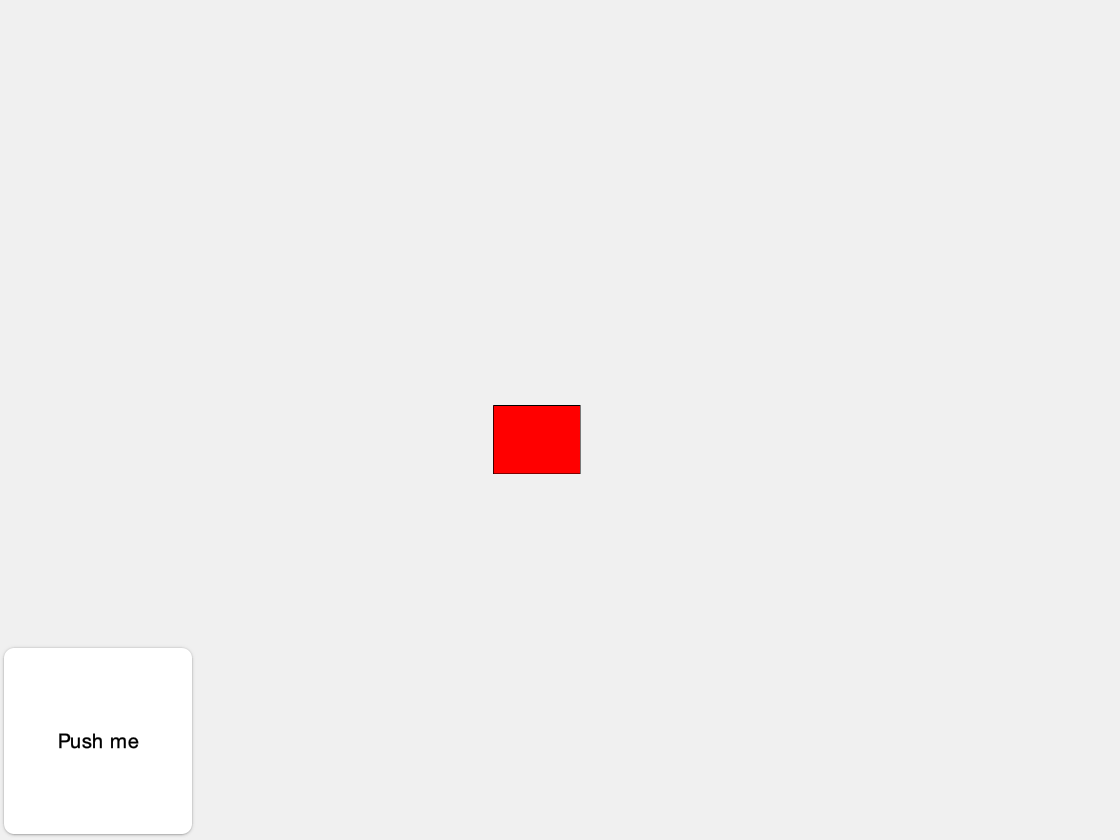

% Create figure
% Create figure and axes that are visible
h1 = figure('Visible','on');
g1 = axes('Visible','off');

% Create a UI control "push button"
button1 = uicontrol('Style','pushbutton','String','Push me','Position',[0,0,100,100]);

% Create an object
hSq = rectangle('Position',[400,400,100,100],'FaceColor','r');

% Assign callback
button1.Callback = {@expandRect,hSq};

xlim([0,1000])
ylim([0,1000])

**Notes:**

- In this case, the callback function is associated with the `uicontrol`, rather than the `figure`. 

- The rectangle needs to be provided to callback function as an additional input.

- We don't need the input corresponding to the uicontrol, so it can be left as a squiggle (`~`).

### MATLAB in "real life"

In this class, we have built our MATLAB code in LiveScript documents because of the text editing capabilities. However, if you use MATLAB outside of this class you will like create your own script and function (.m) files.

***Notes:***

- Creating code for these files is same as creating code inside the code blocks in a LiveScript document.

- `.m` files may be opened with any text editor.

- To "run" a script, it must be saved. However you can use `Cntl` + `Enter` to run a section of the script file without saving.

- Functions should be saved in separate `.m` files and should be located in the `"Current Folder."`

**Example**. Plot $\sin \left(t\right)$ for $t\in \left\lbrack 0,10\right\rbrack$ in a script file. Create a function that changes the plot parameters.

#### Local and nested functions

***Local functions***

- Technically, all functions at the end of a LiveScript document are local functions.

- Local functions can only be invoked by a script or other local functions contained in the same document. This is why you cannot call functions in your LiveScript docuement from the command line.

- As stated previously, local functions compute in workspaces separate from the base MATLAB workspace. In other words, *"what happens in a function, stays in a function (unless passed as an input or output)"*

***Nested functions***

- Nested functions are functions that have been “nested” (like an `if `statement) inside another function.

- Nested functions are often convenient because they can be used to modify variables existing in the parent function without explicitly passing the variables to the nested function.

- Nested functions are used in some of the callback examples in these slides, particularly with respect to keyboard callbacks

**Example: **Create the following nested function in a `.m` file and run it in the command line.

**Notes:**

- In the actual function declaration, the aqua color of variables `a` and `b` indicate that they span (can be seen by) **both** the parent and nested function.

- Variable `c` spans both the parent and nested function.

- All functions must contain an `end` statement.

#### Saving and loading external interface data

In Lecture 26, we needed to load multiple external images. It is a better practice to store all external data needed for a GUI in **one data file**. 

- Saving variables in MATLAB to a data file can be accomplished by using the `save` function

% Not necessary for this example, but let's load the fish and alpha data
[fishPic,~,alphaFish] = imread('fish.png');

% Read the rock picture and associated alpha data
[rockPic,~,alphaRock] = imread('Rock.png');

% Save all image data as a .mat file
save('L27_game.mat','alphaFish','fishPic','rockPic','alphaRock','-mat');

**Note**: for you final project, you can submit one data file with your code.

clear

- Loading data can be accomplished using the `load` function

% Load external data
ex_data = load('L27_game.mat');

- The loaded data will be imported as a structure. Each of the variables above will be stored as fields in this data structure.

% Observed loaded data
ex_data

ex_data = struct with fields:
    alphaFish: [866×1544 uint8]
    alphaRock: [200×300 uint8]
      fishPic: [866×1544×3 uint8]
      rockPic: [200×300×3 uint8]


#### Example problem: a simple game

Building on the material from Topic 25, let's create a simple game in which the goal is to hit a moving fish with a rock.

*This game should have the following features:*

- The user should click where the rock will drop.

- The target is a fish that is randomly moving around.

- If the rock "hits" the fish, then the player's score is incremented by 1 point.

**Important**: as always, try to break this complicated task into smaller, manageable chunks.

**Step 1: create the base visualization of a fish on a blue background**

In Tuesday's lecture, we created a interface for a fish moving randomly. Let's start by first creating a visualization of a fish that can move randomly.

- Use a timer object to dictate the fishes motion

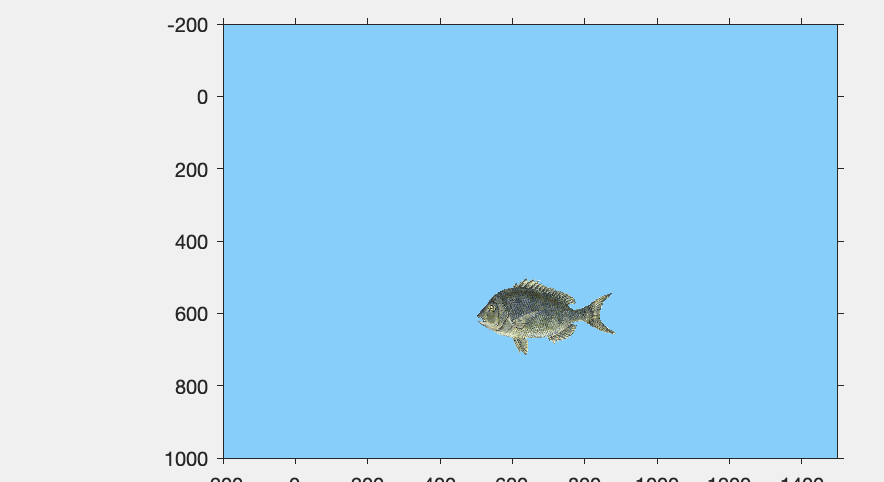

close all

% Step 1: set up figure and GUI
% Create figure and axes that are visible
h1 = figure('Visible','on');
g1 = axes;

% Create data structure to store info and interface
handles = struct;
% Create field to store the current xy direction of fish
handles.moveDir = "left";
% Store the data structure as GUI data
guidata(h1,handles)


% Step 2: create fish object
% Create graphics handle object describing fish
hFish = imshow(ex_data.fishPic);
% Assign alpha data
hFish.AlphaData = ex_data.alphaFish;

% Change scaling of image on axes
hFish.XData = [1,0.25*hFish.XData(2)]+500;
hFish.YData = [1,0.25*hFish.YData(2)]+500;


% Step 3: modify figure properties 
% Ensire axes are visable
g1.Visible = 'on';
% reduce figure window size
h1.Position(3:4) = 0.5*h1.Position(3:4);
% Change the axes background to blue
g1.Color = [135, 206,250]/255;
g1.Position = [0.25,0.05,0.7,0.9];
xlim([-200,1500])
ylim([-200,1000])

**Note**: to access guidata in the command window, simply call the `guidata(<figure>)` in the command line.

**Step 2: enable the fish to move based on a timer object**

In this case, a timer should be created that updates the fish's position every 100 ms. 

- We will base this function off of `'DoWhenKeyIsPressed'` from Topic 25.

- **Note** how we program the fish to move: the `x` movement will oscillate.

- Start simple: only having the fish move for five seconds.

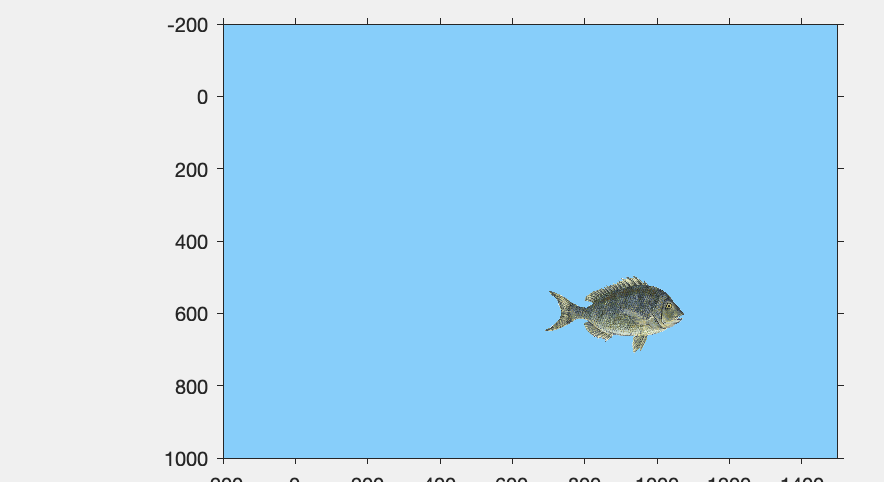

% Timer object
t1 = timer('TimerFcn', {@moveFishRandomly,hFish,h1}, 'ExecutionMode', "fixedRate",'StopFcn',@stopIt,'Period',0.1,'TasksToExecute',50);
start(t1)

**Step 3: incorporate a rock without fish movement**

Continue simple: place a rock object (from Topic 25) at the top of the screen

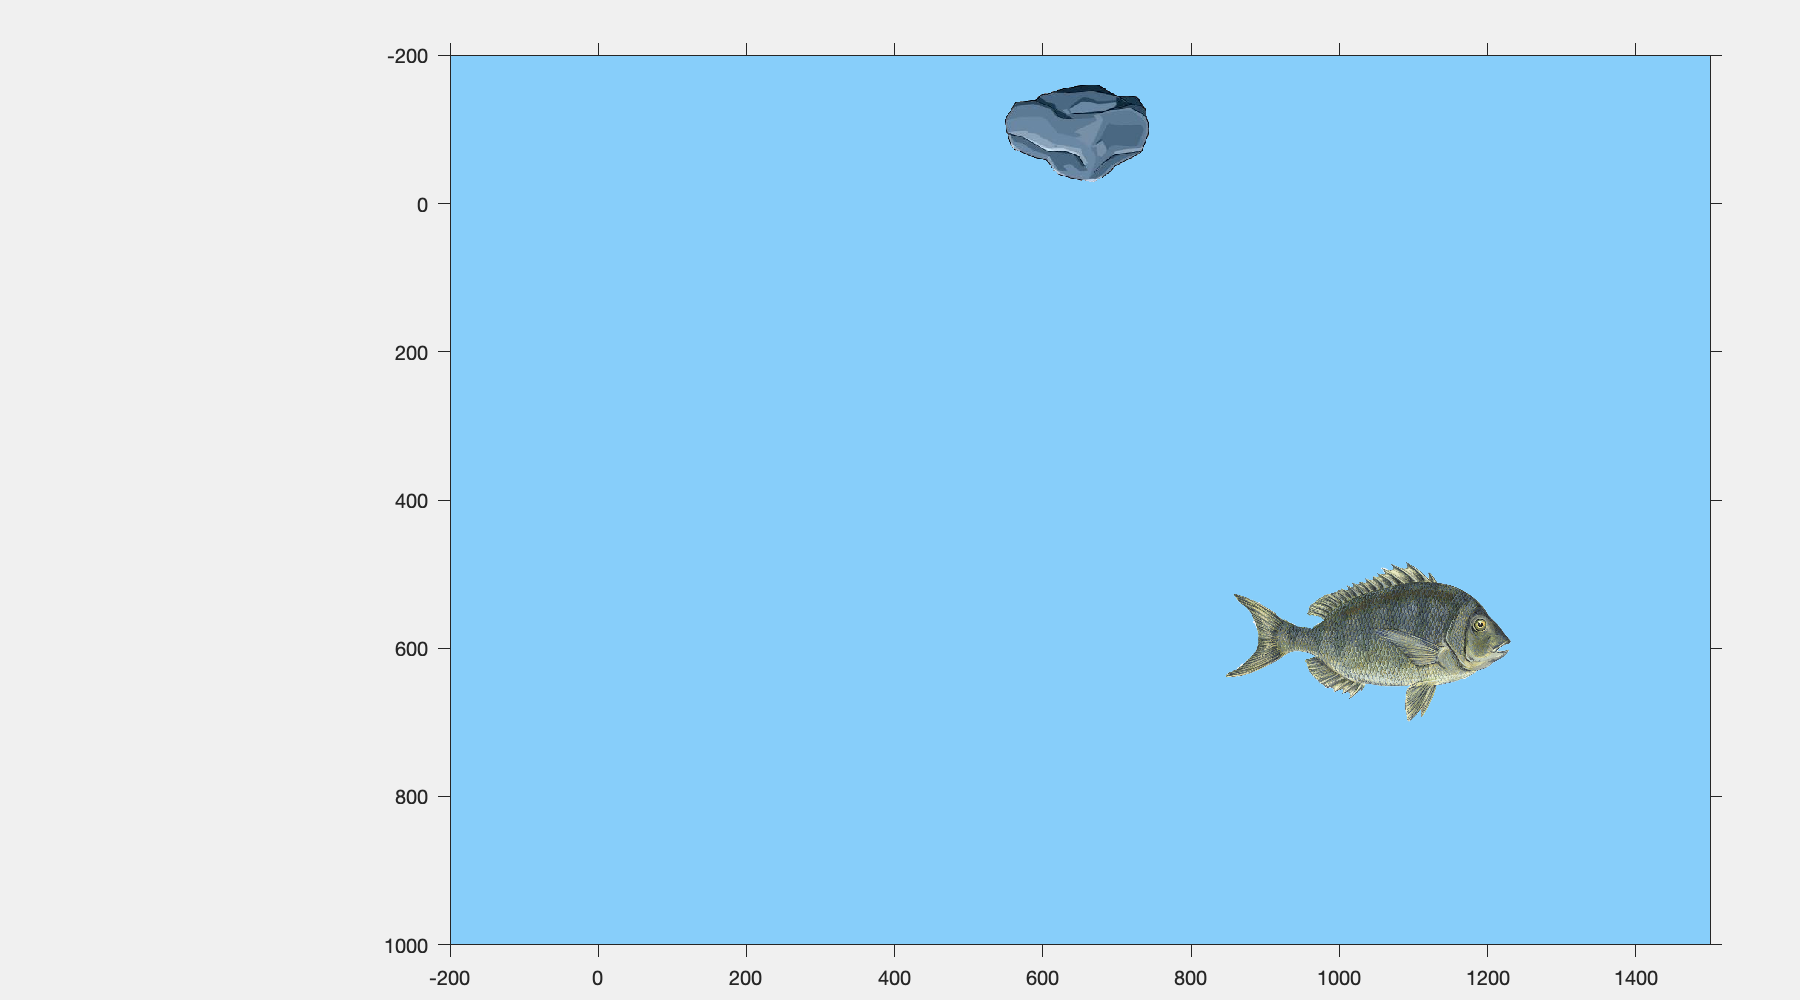

hold on
% Create rock object using the previously loaded rock
% Create graphics handle object describing rock
hRock = imshow(ex_data.rockPic);
hRock.Visible = 'on';
% Assign alpha data
hRock.AlphaData = ex_data.alphaRock;
hold off

% Set position of rock
hRock.XData = hRock.XData + 500;
hRock.YData = -hRock.YData + 1;

% Step 3: Restate graphic parameters
g1.Visible = 'on';
% Reduce figure window size
h1.Position(3:4) = 0.5*h1.Position(3:4);
% Change the axes background to blue
g1.Color = [135, 206,250]/255;
g1.Position = [0.25,0.05,0.7,0.9];
xlim([-200,1500])
ylim([-200,1000])
h1.Position = [672,238,900,500];

**Step 4: incorporate a falling rock**

Now that we have a rock, assign a callback function to animate the "falling rock" upon a mouse click.

- For simplicity, use a callback function similar to that from Topic 25, in which we use a for loop to update the rock's position.

- The function `dropRock2` is contained at the end of this LiveScript document. Note the inputs and what this function accomplishes.

h1.WindowButtonDownFcn = {@dropRock2,hRock};

**Step 5: incorporate a window that depicts a score**

Now that the rock can fall, the next step is to create a score window that can be updated with a score.

- The score window can be created with a `uicontrol` that depicts an updatable score variable.

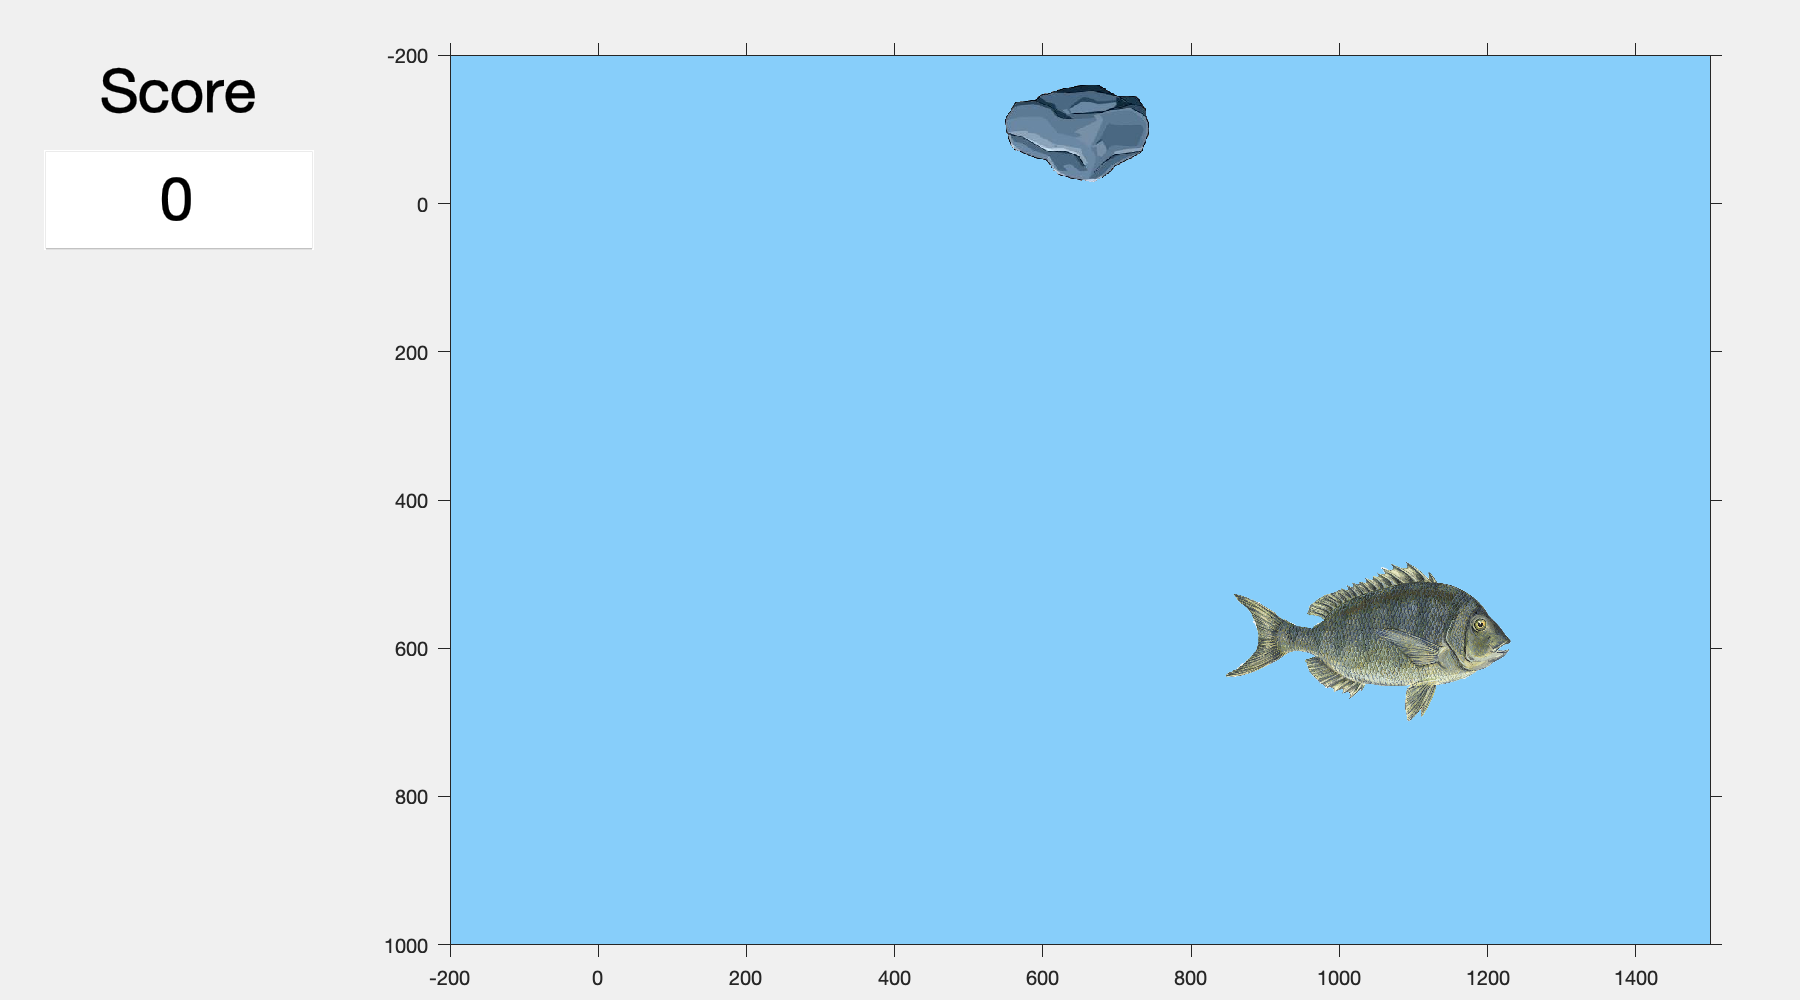

handles.score = 0;
guidata(h1,handles);

% Add an "edit text" box to show the current value of teh counter
hedit = uicontrol('Style', 'edit', 'Units', 'Normalized', 'Position', [0.025,0.75,0.15,0.1],'FontSize',30,'String',handles.score);
% Simply display text that says 'Score'
uicontrol('Style','text','Units','Normalized','Position', hedit.Position + [0,0.1,0,0],'FontSize',30,'String','Score');

**Step 6: Incremement the score when the rock "hits"**

The score should update whenever the rock gets within *some* distance of the fish.

**Note**: in which piece of code should the score be updated?

- It makes sense to update the score in the `dropRock` function, because that is where the position of the rock is updated.

- Consider the following function, `dropRock3`, which updates the score whenever the rock is within 100 units of the fish.

% Update the callback function with this new variable
h1.WindowButtonDownFcn = {@dropRock3,hRock,hedit,hFish};

**Step 7: Test with the fish moving around**

Using the same timer as before, test with the fish moving around.

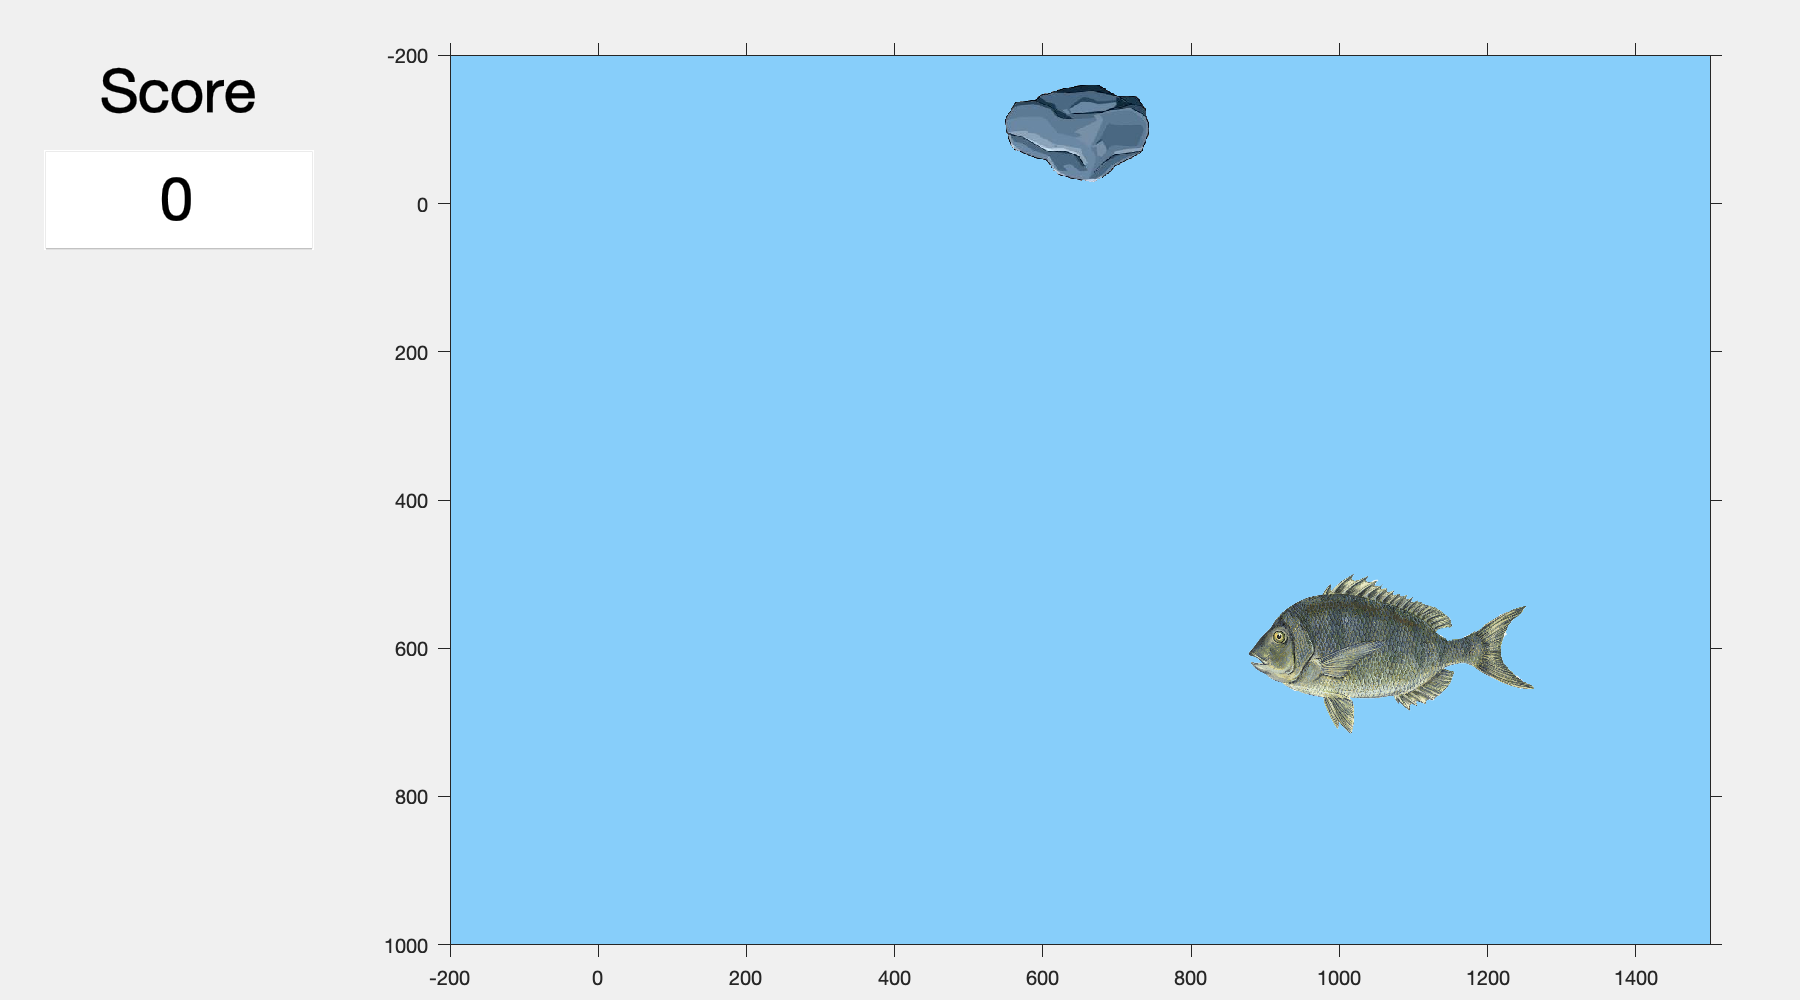

% Timer object
t1 = timer('TimerFcn',{@moveFishRandomly,hFish,h1},'ExecutionMode',"fixedRate", 'StopFcn',@stopIt,'Period',0.1,'TasksToExecute',100);
start(t1)

**Note**: you might observe that the motion is a little laggy

**Step 8: Change the rock motion to be based on a timer**

To increase our precision of the rock movement, create a timer object that changes the rocks position every 100 ms. 

- **Where should this timer go?** It should go in the `dropRock` function because this is what triggers the rock movement.

- Update the mouse callback function with `dropRock4.` **Note the nested functions in this callback function.**

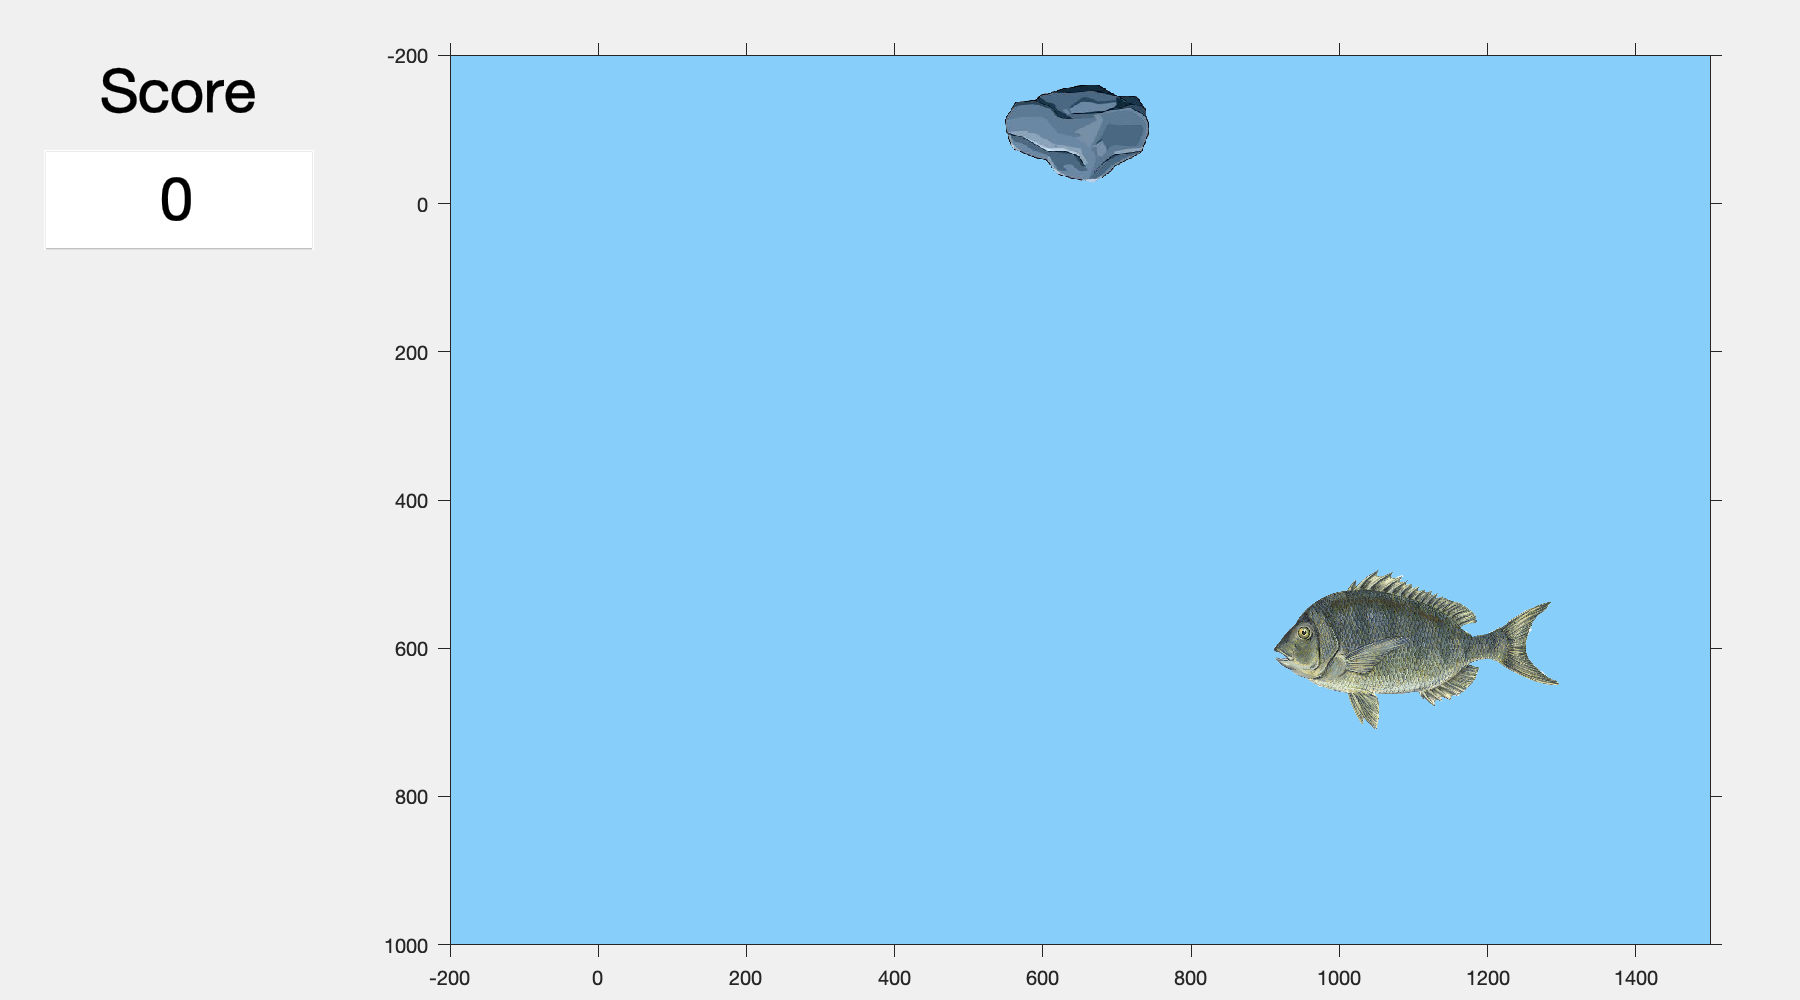

h1.WindowButtonDownFcn = {@dropRock4,hRock,hedit,hFish};
% Timer object
t1 = timer('TimerFcn',{@moveFishRandomly,hFish,h1},'ExecutionMode',"fixedRate", 'StopFcn',@stopIt,'Period',0.1,'TasksToExecute',100);

start(t1)

**Step 9: Allow the user to drop the rock from various positions**

Now that the movement should be smoother, make one last addition: the ability to change the location of where the rock is dropped.

- We can access the current position of the mouse using the 'CurrentPoint' property of the axis object.

- `dropRock5` incorporates this information:

h1.WindowButtonDownFcn = {@dropRock5,hRock,hedit,hFish};

% Timer object
t1 = timer('TimerFcn',{@moveFishRandomly,hFish,h1},'ExecutionMode',"fixedRate", 'StopFcn',@stopIt,'Period',0.1,'TasksToExecute',100);




We have thus made a simple game! 

**Takeaway**: start small, plan out your approach, take it on one step at a time. **It is ok to have redo or change an aspect.**

#### Creating interfaces with `guide`

So far, we have created user interfaces directly by creating `uicontrol` objects in a (parent) figure window. This figure window contains the "user interface." User interfaces can also be created by using GUIDE (`guide`) or appdesigner (not discussed here).

`uicontrol`:

- Often used when only a few control objects are present.

- Invoke with `uicontrol()` in a function or script file

`guide`:

- Visual development environment that streamlines incorporating multiple objects.

- Type `guide` at the command line to launch the GUI editor.

MATLAB’s `guide` provides an easy to use design interface that provides the user with an interactive figure onto which buttons, drop-down lists, text boxes, etc. can be added

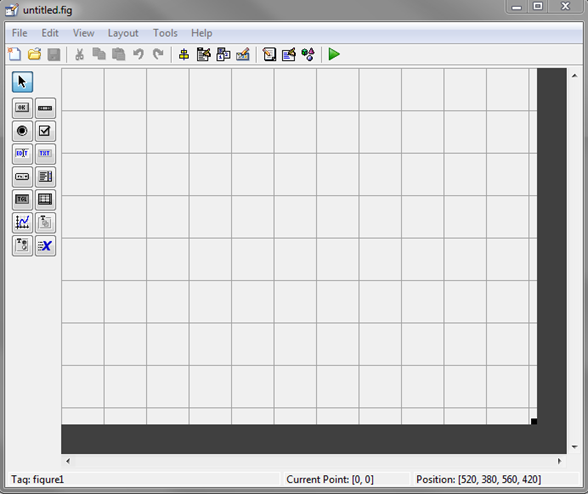

`guide `creates two files associated with the GUI - the figure window (`.fig` format) and the underlying code (`.m` file). The `.m` file is created when the GUI is first saved and updates as control objects are added.

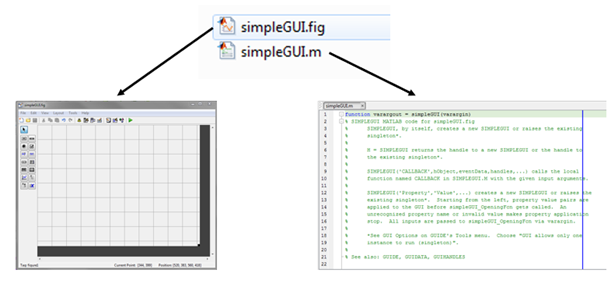

Guide automatically creates a large amount of code at the beginning of the underlying `.m` file that

- opens the GUI figure when the code is run

- passes arguments into and out of the GUI

- communicates data between figures and control objects

**Adding interactive/visual elements in **`guide`

- GUI objects (buttons, axes, etc.) can be dragged and dropped onto the figure canvas from the menu to the left of the `guide` editor

**Referencing visual elements in **`guide`

- Each object has an associated tag that is used to reference that object

- Properties of the object can be queried through the property inspector (double click on element or right click>property inspector)

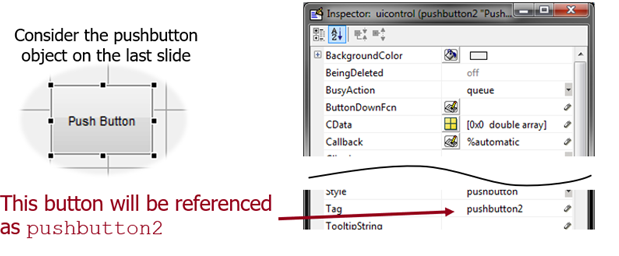

**Callbacks in **`guide`

- Each object can initiate a callback in the underlying .m file

- The callback executes code upon manipulation of the object (pushing a button, selecting from a listbox or pulldown menu item, changing a slider value, etc.)

**Communicating variables between callbacks in **`guide`

- You may recall that callbacks cannot return outputs

- Variables are passed among callbacks in `guide` using `guidata``()`and do not persist across functions unless explicitly written to the `handles` variables/structure

`guide`** examples**

- `currentTimeGUI.m/.fig` queries the current time with a pushbutton and writes the result to a text box

- `sinePlotGUI.m/.fig` adds a y-offset to a sine wave depending on the pushbutton pushed

#### **Functions for Topic 26 stored here:**

- **Example: uicontrol example**

function expandRect(~,~,hSq)
    % Callback function associated with the pushbutton
    hSq.Position(3:4) = hSq.Position(3:4) + 10;
    drawnow;
    
end

- **Example: timer stop function, from Topic 25**


function stopIt(t,~)
    % Timer StopFcn callback.
    disp('The timer ''StopFcn'' just executed.')
    disp(['It utilizes the first input of the callback, '...
        'the handle of the timer, to stop the timer.'])
    disp('Always delete timers after you are done using them.')
    
    delete(t)
end

- **Step 2**

function moveFishRandomly(t1,~,hFish,h1)
    % Utilizes keypresses to move the x/y coordinates of the
    % ball or closes the figure.
    
    % Load GUI data
    % Create field to store the current xy direction of fish
    handles = guidata(h1);
    
    %Fish movement. Note that the fish will oscillate across the screen.
    dy = 10*rand(1)-5;
    dx = 50*cos(t1.TasksExecuted*2*pi/50);
    
    % Move in y direction
    hFish.YData = hFish.YData + dy;
    
    % Move in x direction. NOTE: we are ensuring that the fish is pointed
    % in the correct direction
    if dx < 0
        if handles.moveDir == "left" 
            hFish.XData = hFish.XData + dx;
        else
            hFish.XData = fliplr(hFish.XData) + dx;
            handles.moveDir = "left";
        end
    else
        if handles.moveDir == "right" 
            hFish.XData = hFish.XData + dx;
        else
            hFish.XData = fliplr(hFish.XData) + dx;
            handles.moveDir = "right";
        end
    end

    % Store the data structure as GUI data
    guidata(h1,handles);
end

- **Step 4**

function dropRock2(~,~,hRock)
    % Timer function that is called everytime the rock should be dropped 
    
    % Loop through time steps and move the rock down by some known amount
    % of time
    for k = 1:12
        hRock.YData = hRock.YData + 100;
        pause(0.1)
        drawnow
    end
    
    % Reset position of rock
    hRock.YData = [-200,-1];
    drawnow
end

- **Step 6**

function dropRock3(h1,~,hRock,hedit,hFish)
    % Timer function that is called everytime the rock should be dropped 
    handles = guidata(h1);
    
    % Loop through time steps and move the rock down by some known amount
    % of time
    for k = 1:12
        % Update position of rock
        hRock.YData = hRock.YData + 100;
        
        % Calculate the distance from the fish to the rock
        fishCenter = [mean(hFish.XData),mean(hFish.YData)];
        rockCenter = [mean(hRock.XData),mean(hRock.YData)];
        distance = fishCenter - rockCenter;
        distance = sqrt(sum(distance.^2));
        
        % If the distance is less than 100 units, update the score
        if distance < 100
            handles.score = handles.score + 1;
            hedit.String = handles.score;
        end
        
        pause(0.1)
        drawnow
    end
    
    % Reset position of rock
    hRock.YData = [-200,-1];
    drawnow
    
    % Save guidata
    guidata(h1,handles);
end

- **Step 8**

function dropRock4(h1,~,hRock,hedit,hFish)
    % Timer function that is called everytime the rock should be dropped 
    handles = guidata(h1);
    
    % Use a timer object to update the positions of the rock
    t2 = timer('TimerFcn',@incrementRock,'ExecutionMode',"fixedRate",...
        'StopFcn',@stopTimer,'Period',0.1,'TasksToExecute',12);
    
    start(t2)

    % Nested function 1: occurs every time the timer "fires"
    function incrementRock(~,~)
        
        % Update position of rock
        hRock.YData = hRock.YData + 100;
        
        % Calculate the distance from the fish to the rock
        fishCenter = [mean(hFish.XData),mean(hFish.YData)];
        rockCenter = [mean(hRock.XData),mean(hRock.YData)];
        distance = fishCenter - rockCenter;
        distance = sqrt(sum(distance.^2));
        
        % If the distance is less than 100 units, update the score
        if distance < 100
            handles.score = handles.score + 1;
            hedit.String = handles.score;
            guidata(h1,handles);
        end
        drawnow
    end

    % Nested function 2: occurs at the end of the "rock dropping" sequence
    function stopTimer(t,~)
        % Reset position of rock
        hRock.YData = [-200,-1];
        delete(t);
    end
end

- **Step 9**

function dropRock5(h1,~,hRock,hedit,hFish)
    % Load guidata
    handles = guidata(h1);
    
    % Get the location of the mouse.
    pos = get(gca,'CurrentPoint');
    xMouse = pos(1,1);
    yMouse = pos(1,2);
    
    % Once clicked, the left boundary of where the rock will be dropped
    % from will be set by the x coordinates of the mouse
    hRock.XData = [0,diff(hRock.XData)] + xMouse;
    

    % Timer object
    t2 = timer('TimerFcn',@incrementRock,'ExecutionMode',"fixedRate",...
        'StopFcn',@stopTimer,'Period',0.1,'TasksToExecute',12);
    start(t2)

    % Nested function 1: occurs every time the timer "fires"
    function incrementRock(~,~)
        
        % Update position of rock
        hRock.YData = hRock.YData + 100;
        
        % Calculate the distance from the fish to the rock
        fishCenter = [mean(hFish.XData),mean(hFish.YData)];
        rockCenter = [mean(hRock.XData),mean(hRock.YData)];
        distance = fishCenter - rockCenter;
        distance = sqrt(sum(distance.^2));
        
        % If the distance is less than 100 units, update the score
        if distance < 100
            handles.score = handles.score + 1;
            hedit.String = handles.score;
            guidata(h1,handles);
        end
        drawnow
    end

    % Nested function 2: occurs at the end of the "rock dropping" sequence
    function stopTimer(t,~)
        % Reset position of rock
        hRock.YData = [-200,-1];
        delete(t);
    end
end
